## PSO: Colisiones y Control Diferencial

*IE3038 - Diseño e Innovacion de Ingeniería*

*Autor: Eduardo Andrés Santizo Olivet (16089)*

*Descripcion: Uso del algoritmo de PSO implementando colisiones y control diferencial*

### Setup / Parámetros PSO

clear;                                                      % Se limpian las variables del workspace
clear ComputeInertia;                                       % Se limpian las variables persistentes presentes dentro de "ComputeInertia.m"

NoParticulas = 10;                                          % No. de partículas
PartPosDims = 2;                                            % No. de variables a optimizar / No. de dimensiones sobre las que se pueden desplazar las partículas.

CostFunc = "Himmelblau";                                      % Función de costo a optimizar. Escribir "help CostFunction" para más información
Multiples_Min = 1;                                          % La función de costo tiene múltiples mínimos? Consultar "help CostFunction" para ver número de mínimos por función.

DimsMesa = 12;                                              % Dimensiones de mesa de simulación (Metros)
PosMax = DimsMesa / 2;                                      % Posición máx: Valor máx. para las coordenadas X y Y de las partículas (Asumiendo un plano de búsqueda cuadrado)
PosMin = -PosMax;                                           % Posición mín: Negativo de la posición máxima

InitTime = 0;                                               % Tiempo de inicio del algoritmo (0s)
EndTime = 10;                                               % Duración de algoritmo en segundos 
dt = 0.01;                                                  % Tiempo de muestreo, diferencial de tiempo o "time step"
IteracionesMax = ceil((EndTime - InitTime) / dt);           % Iteraciones máximas que podrá llegar a durar la simulación.

RadioPuck = 0.35;                                           % Radio del Cuerpo del EPuck en metros
%rng(666);                                                    % 29 = 1 colision

### Inicialización de Criterios de Convergencia

Criterios_Activados = [];                                   % El vector de criterios activados es nulo
Criterios = zeros(1,4);                                     % Se inicializan todos los criterios como "No alcanzados" (Iguales a cero)

### Búsqueda Numérica del Mínimo de la "Cost Function"

% Imaginar que se tiene un plano coordenado que va tanto en X y Y desde PosMin a PosMax 
% con un step de 0.01. MeshX consiste de todas las coordenadas X de ese plano y MeshY 
% consiste de todas las coordenadas Y de ese plano. 
Resolucion = 0.01;
[MeshX, MeshY] = meshgrid(PosMin:Resolucion:PosMax, PosMin:Resolucion:PosMax);

% Se redimensionan MeshX y MeshY como vectores columna y luego se concatenan. El resultado 
% es una matriz de dos columnas (Coordenadas X y Y) donde las filas consisten de todas las 
% posibles combinaciones de coordenadas que pueden existir en el plano de búsqueda. 
Mesh2D = [reshape(MeshX, [], 1) reshape(MeshY, [], 1)];

% NOTA: El programa debería ser capaz de identificar numéricamente los mínimos de la función 
% evaluando los puntos del mesh en la cost function. En caso no se detecten bien. Disminuir 
% el valor de resolución o revisar si la opción de "Multiples_Min" está habilitada (En caso
% se esté utilizando una función de múltiples mínimos.
Altura = reshape(CostFunction(Mesh2D,CostFunc), size(MeshX, 1), size(MeshX, 2));        % Evaluación de todas las coords. del plano en la "Cost Function". El "output vector" (Nx1) se redimensiona a la forma de MeshX
MaxAltura = max(max(Altura));                                                           % Se obtiene el costo máximo de todo el plano.
MinAltura = min(min(Altura));                                                           % Se obtiene el costo mínimo de todo el plano.

if Multiples_Min                                                                        % Utilizar un threshold de detección más bajo para funciones con múltiples mínimos globales.
    Threshold_Cercania = 10^-2;                                                         % Modificar en caso no se detecten bien todos los mínimos globales de una función con múltiples mínimos absolutos.
else             
    Threshold_Cercania = 10^-5;     
end

IndexMin = find(abs(reshape(Altura,[],1) - MinAltura) < Threshold_Cercania);            % Distancia del mínimo del plano al resto de puntos. Se retornan las coordenadas de los puntos a una distancia < "Threshold_Cercania"
Coords_Min = Mesh2D(IndexMin,:);                                                        % Coordenadas (Fila de Mesh2D) donde se encuentra el/los costo(s) mínimo(s) global(es)

% Se limpian los mínimos encontrados en caso se hayan detectado réplicas de
% la misma coordenada. Útil debido a la forma numérica y algo "brute forced"
% de la solución utilizada para encontrar mínimos.
i = 1;
while i < size(Coords_Min,1)
    DistMins = sqrt(sum((Coords_Min - Coords_Min(i,:)).^2, 2));                         % Se calcula la distancia euclideada del mínimo "i" al resto.
    Coords_Min((DistMins < 0.1) & (DistMins ~= 0),:) = [];                              % Se eliminan las filas de "Coords_Min" cuya distancia euclideada sea menor a 0.1 y distinta de 0.
    i = i+1;
end

### Coeficientes de Constricción / Coeficiente de Inercia

De acuerdo con Poli, Kennedy y Blackwell (2007) en su artículo: "Particle Swarm Optimization - Swarm Intelligence", el algoritmo de PSO original tenía la siguiente forma


$$v\left(t+1\right)=v\left(t\right)+\vec{U} \left(0,\phi_1 \right)\otimes \left(\vec{p_{\mathrm{local}} } -\vec{x_i } \right)+\vec{U} \left(0,\phi_2 \right)\otimes \left(\vec{p_{\mathrm{global}} } -\vec{x_i } \right)$$



$$x\left(t+1\right)=x\left(t\right)+v\left(t+1\right)$$


Donde:

- $\overrightarrow{U} \left(0,\phi_1 \right)$: Consiste de un número uniformemente distribuido entre 0 y $\phi_1 \;$

- $\otimes$: Consiste del "element-wise product".

Este presentaba ciertos problemas de inestabilidad, en particular porque el término de la velocidad actual ($v\left(t\right)$) tendía a crecer desmesuradamente. Para limitarlo, la primera solución propuesta por Kennedy y Eberhart (1995) fue truncar los posibles valores que podía llegar a tener la velocidad de una partícula a un valor entre (-Vmax, Vmax). Esto producía mejores resultados, pero la selección de Vmax requería de una gran cantidad de pruebas para poder obtener un valor óptimo para la aplicación dada. Poco después Shi y Eberhart (1998) propusieron una modificación a la regla de actualización de la velocidad de las partículas: La adición de un coeficiente $\omega$ multiplicando a la velocidad actual.


$$v\left(t+1\right)=\omega \;v\left(t\right)+\overrightarrow{U} \left(0,\phi_1 \right)\otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+\overrightarrow{U} \left(0,\phi_2 \right)\otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)$$


A este término se le denominó coeficiente de inercia, ya que si se hace un análogo entre la regla de actualización y un sistema de fuerzas, el coeficiente representa la aparente "fluidez" del medio en el que las partículas se mueven. La idea de esta modificación era iniciar el algoritmo con una fluidez alta ($\omega =0\ldotp 9$) para favorecer la exploración y reducir su valor hasta alcanzar una fluidez baja  ($\omega =0\ldotp 4$) que favorezca la agrupación y convergencia. Existen múltiples métodos para seleccionar y actualizar $\omega$. Finalmente, el método más reciente para limitar la velocidad consiste de aquel propuesto por Clerc y Kennedy (2001). En este, se modeló al algoritmo como un sistema dinámico y se obtuvieron sus eigenvalores. Se pudo llegar a concluir que, mientras dichos eigenvalores cumplieran con ciertas relaciones, el sistema de partículas siempre convergería. Una de las relaciones más fáciles y computacionalmente eficientes de implementar consiste de la siguiente modificación al PSO:


$$v\left(t+1\right)=\chi \;\left(\;v\left(t\right)+\overrightarrow{U} \left(0,\phi_1 \right)\otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+\overrightarrow{U} \left(0,\phi_2 \right)\otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)\right)$$



$$\chi =\frac{2}{\phi -2+\sqrt{\;\phi {\;}^2 -4\phi \;}}$$



$$\phi =\phi_1 +\phi_2 >4$$


Al implementar esta constricción (Generalmente utilizando $\phi_1 =\phi_2 =2\ldotp 05$), se asegura la convergencia en el sistema, por lo que teóricamente ya no es necesario truncar la velocidad. Un aspecto importante a mencionar es que comúnmente se tiende a distribuir la constante $\chi$ en toda la expresión de la siguiente manera:


$$v\left(t+1\right)=\chi \;\;v\left(t\right)+\chi \overrightarrow{U} \left(0,\phi_1 \right)\otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+\chi \overrightarrow{U} \left(0,\phi_2 \right)\otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)$$



$$\left.v\left(t+1\right)=\chi \;\;v\left(t\right)+C_1 \otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+C_2 \otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)\right)$$


Aquí se puede llegar a ver más claramente como $\chi$ consiste del nuevo valor para el coeficiente de inercia, por lo que la adición de una constante $\omega$ sería redundante o incluso detrimental para el algoritmo (Ya que introduce efectos imprevistos en la estabilidad del sistema). De cualquier manera se puede experimentar incluyendo ambas constantes y observando los efectos que su adición simultánea tiene en el sistema.


% -------------------------------------------------------------------------
% A continuación se presentan tres opciones para restringir la velocidad: 
%   - Utilizar el coeficiente de constricción (Chi) limitando Vmax a Xmax
%   - Utilizar un coeficiente de inercia limitando Vmax a un valor elegido 
%     por el usuario
%   - Mezclar ambos métodos. Método utilizado por Aldo Nadalini en su tésis.
% -------------------------------------------------------------------------

Restriccion = "Mixto";                                                   % Modo de restricción: Inercia / Constriccion / Mixto

switch Restriccion
    
    % Coeficiente de Inercia ====
    % Para el coeficiente de inercia, se debe seleccionar el método que se desea utilizar. 
    % En total se implementaron 5 métodos distintos. Escribir "help ComputeInertia" para 
    % más información.
    
    case "Inercia"
        TipoInercia = "Chaotic";                                                    % Consultar tipos de inercia utilizando "help ComputeInertia"
        Wmax = 0.9; Wmin = 0.4;
        W = ComputeInertia(TipoInercia, 1, Wmax, Wmin, IteracionesMax);             % Cálculo de la primera constante de inercia.
        
        VelMax = 0.2*(PosMax - PosMin);                                             % Velocidad máx: Largo max. del vector de velocidad = 20% del ancho/alto del plano 
        VelMin = -VelMax;                                                           % Velocidad mín: Negativo de la velocidad máxima
        Chi = 1;                                                                    % Igualado a 1 para que el efecto del coeficiente de constricción sea nulo
        Phi1 = 2; Phi2 = 2;
        
    % Coeficiente de Constricción ====
    % Basado en la constricción tipo 1'' propuesta en el paper por Clerc y Kennedy (2001) 
    % titulado "The Particle Swarm - Explosion, Stability and Convergence". Esta constricción 
    % asegura la convergencia siempre y cuando Kappa = 1 y Phi = Phi1 + Phi2 > 4.

    case "Constriccion"
        Kappa = 1;                                                                  % Modificable. Valor recomendado = 1
        Phi1 = 2.05;                                                                % Modificable. Coeficiente de aceleración local. Valor recomendado = 2.05.
        Phi2 = 2.05;                                                                % Modificable. Coeficiente de aceleración global. Valor recomendado = 2.05
        Phi = Phi1 + Phi2;
        Chi = 2*Kappa / abs(2 - Phi - sqrt(Phi^2 - 4*Phi));
        
        W = 1;
        VelMax = PosMax;                                                            % Velocidad máx: Igual a PosMax
        VelMin = PosMin;                                                            % Velocidad mín: Igual a PosMin
    
    % Ambos Coeficientes (Mixto) ====
    % Utilizado por Aldo Nadalini en su tésis "Algoritmo Modificado de Optimización de 
    % Enjambre de Partículas (MPSO) (2019). Chi se calcula de la misma manera, pero se
    % utiliza un Phi1 = 2, Phi2 = 10 y el coeficiente de inercia exponencial decreciente.
    
    case "Mixto"
        Kappa = 1;                                                                  % Valor recomendado = 1
        Phi1 = 2;                                                                   % Valor recomendado = 2
        Phi2 = 10;                                                                  % Valor recomendado = 10
        Phi = Phi1 + Phi2;
        Chi = 2*Kappa / abs(2 - Phi - sqrt(Phi^2 - 4*Phi));
        
        TipoInercia = "Exponent1";                                                  % Tipo de inercia recomendada = "Exponent1"
        Wmax = 1.4; Wmin = 0.5;
        W = ComputeInertia(TipoInercia, 1, IteracionesMax);                         % Cálculo de la primera constante de inercia utilizando valores default (1.4 y 0.5).
        
        VelMax = inf;                                                               % Velocidad máx: Sin restricción
        VelMin = -inf;                                                              % Velocidad mín: Sin restricción
    
    % Mixed Discrete PSO (MDPSO) ====
    % Propuesto por Chowdhury, et al. en el paper "A Mixed-Discrete PSO Algorithm with
    % Explicit Diversity-Preservation" y luego utilizado por Juan Pablo Cuahueque en su 
    % tesis (2019). Este evita la aglomeración temprana de las partículas utilizando una
    % técnica denominada "Diversity preservation".
    case "MDPSO"
        Alpha = 400;                                                                % Parámetro cognitivo
        Beta = 50;                                                                  % Parámetro social
        Gamma = 40;                                                                 % Coeficiente de preservación de diversidad
end

### Inicialización de Posiciones, Velocidades y Costos

Posicion_Actual = unifrnd(PosMin, PosMax, [NoParticulas PartPosDims]);          % Posición (Random) de todas las partículas. Distribución uniforme.     Dims: NoParticulas X VarDims
Posicion_Previa = Posicion_Actual;                                              % Memoria con la posición previa de todas las partículas.               Dims: NoParticulas x VarDims
Posicion_LocalBest = Posicion_Actual;                                           % Las posiciones que generaron los mejores costos en las partículas     Dims: NoParticulas X VarDims
Velocidad = zeros([NoParticulas PartPosDims]);                                  % Velocidad de todas las partículas. Inicialmente 0.                    Dims: NoParticulas X VarDims
Costo_Local = CostFunction(Posicion_Actual, CostFunc);                          % Evaluación del costo en la posición actual de la partícula.           Dims: NoPartículas X 1 (Vector Columna)
Costo_LocalBest = Costo_Local;

[Costo_GlobalBest, Fila] = min(Costo_LocalBest);                                % "Global best": El costo más pequeño del vector "CostoLocal"           Dims: Escalar
Posicion_GlobalBest = Posicion_Actual(Fila, :);                                 % "Global best": Posición que genera el costo más pequeño               Dims: 1 X VarDims

Costo_History = zeros([IteracionesMax 1]);                                      % Historial de todos los "Costo_Global" o global best de cada iteración
Costo_History(1) = Costo_GlobalBest;                                            % La primera posición del vector es el primer "Global Best"

### Settings de Gráficación / Setup Gráficos

ModoVisualizacion = "2D";                                                       % Modo de visualización: 2D, 3D o None.
SaveFrames = 0;                                                                 % Guardar frames de animación: 1 = Si / 0 = No.
FrameSkip = 3;                                                                  % Cada cuantas frames se toma un screenshot. Valor recomendado = 3

if ~strcmp(ModoVisualizacion, "None")
    figure(1); clf;                                                             % Se limpia la figura 1
    figure('visible','on');                                                     % Opcional. Utilizado para mostrar animaciones en un ".mlx". Si se utiliza un ".m" se puede comentar.
    axis equal;                                                                 % Ejes con escalas iguales y cuadrícula habilitada.
    
    FigureWidth = 900;                                                          % Ancho del plot en "pts"
    FigureHeight = 400;                                                         % Alto del plot en "pts"
    ScreenSize = get(0,'ScreenSize');                                           % Se obtiene el tamaño de la pantalla. ScreenSize(3) = Ancho / ScreenSize(4) = Alto
    
    % Centra la figura en pantalla
    set(gcf, 'Position',  [ScreenSize(3)/2 - FigureWidth/2, ScreenSize(4)/2 - FigureHeight/2, FigureWidth, FigureHeight])
        
    % Subplot 2 (Fila 1, Columna 2): Graficación de partículas
    subplot(1, 2, 2);
    switch ModoVisualizacion
        case "2D"
            axis([PosMin PosMax PosMin PosMax]);                                                                                % Limites Plot: Tanto X como Y van de PosMin a PosMax 
            PlotSupCosto = contour(MeshX, MeshY, Altura);                                                                       % Contour Plot: Curvas de nivel de función o superficie de costo
            hold on; alpha 0.5; grid on;                                                                                        %   Graficar en el mismo plot / Transparencia del 50%
            
            % El radio del puck está en metros, pero debe ser reexpresado en puntos
            % para ser utilizado en "scatter()" y "scatter3()"
            ax = gca;                                                               % Propiedades de "axis" o ejes actuales
            old_units = get(ax, 'Units');                                           % Unidades de los ejes actuales
            set(ax, 'Units', 'points');                                             % Se cambian las unidades de los ejes a puntos
            PosAxis = get(ax, 'Position');                                          % Se obtiene el [left bottom width height] de la caja que encierra a los ejes
            set(ax, 'Units', old_units);                                            % Se regresa a las unidades originales de los ejes
            DimsMesaPuntos = min(PosAxis(3:4));                                     % Se obtiene el valor mínimo entre el "width" y el "height" de los axes en "points"
            FactorConversion = DimsMesaPuntos / DimsMesa;
            AreaPuckScatter = pi*(RadioPuck * FactorConversion)^2;
            
            PlotParticulas = scatter(Posicion_Actual(:,1), Posicion_Actual(:,2), AreaPuckScatter, 'blue', 'LineWidth', 1.5);    % Scatter Plot: Partículas. Puntos azules.
            PlotPuntoMin = scatter(Coords_Min(:,1), Coords_Min(:,2), 'red', 'x');                                               %   Mín función de costo = Cruz roja
            
        case "3D"
            axis([PosMin PosMax PosMin PosMax], 'vis3d');                                                                       % Limites Plot: X y Y de (PosMin, PosMax). Z de (MinAltura, MaxAltura) 
            PlotSupCosto = surf(MeshX, MeshY, Altura);                                                                          % Surface Plot: Superficie o función de costo 
            hold on; shading interp; alpha 0.5; grid on                                                                         %   Graficar en el mismo plot / Paleta de color "interp" / Transparencia del 50% 
            PlotParticulas = scatter3(Posicion_Actual(:,1), Posicion_Actual(:,2), Costo_Local, [], 'blue', 'filled');           % Scatter Plot: Partículas. Puntos azules
            h = rotate3d;
            h.Enable = 'on';                                                                                                    % Se permite que el usuario rote la gráfica    
    end
    
    title({"Función Costo: " + CostFunc});
    xlabel('X_1');
    ylabel('X_2');
    zlabel('Costo'); 
    
    % Subplot 1 (Fila 1, Columna 1): Minimización de Función de Costo
    SubplotCosto = subplot(1, 2, 1);
    PlotCosto = plot(1, Costo_History(1), 'LineWidth', 2);                                                              % Regular Plot: Historia de los mejores costos obtenidos por el PSO.
    title({"Minimización de Función de Costo" ; "Iteraciones Actuales: " + num2str(i)});
    xlabel('Iteración');
    ylabel('Costo Óptimo');
    grid on;
    
    hold off;
    
end

### Main Loop

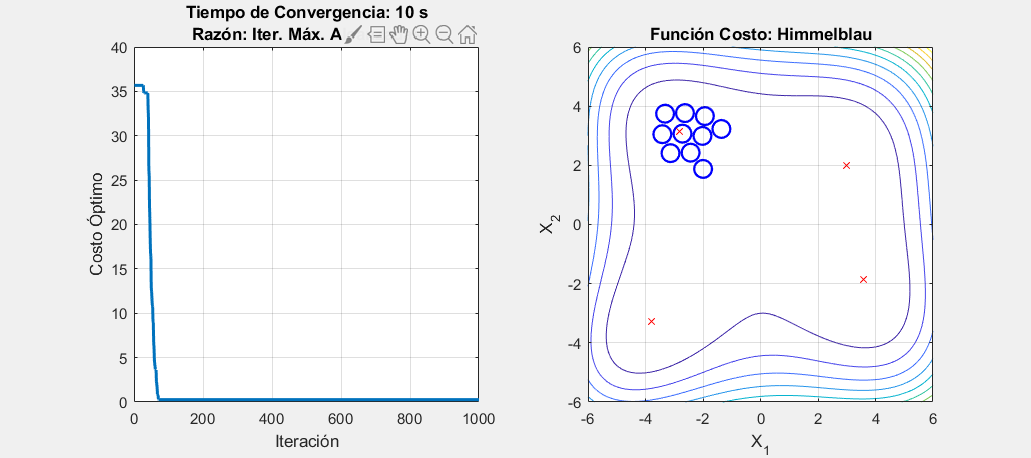

Iteraciones = 0;
Frame = 0;

for i = 2:IteracionesMax
    
    R1 = rand([NoParticulas PartPosDims]);                                          % Números normalmente distribuidos entre 0 y 1
    R2 = rand([NoParticulas PartPosDims]);
        Posicion_Previa = Posicion_Actual;
    
    % Actualización de Velocidad
    Velocidad = Chi * (W * Velocidad ...                                            % Término inercial
                    + Phi1 * R1 .* (Posicion_LocalBest - Posicion_Actual) ...       % Componente cognitivo
                    + Phi2 * R2 .* (Posicion_GlobalBest - Posicion_Actual));        % Componente social
    
    Velocidad = max(Velocidad, VelMin);                                             % Se truncan los valores de velocidad en el valor mínimo y máximo
    Velocidad = min(Velocidad, VelMax);
    
    % Actualización de Posición
    Posicion_Actual = Posicion_Actual + Velocidad * dt;                             % Actualización "discreta" de la posición. El algoritmo de PSO original asume un sampling time = 1s.
    Posicion_Actual = max(Posicion_Actual, PosMin);                                 % Se truncan los valores de posición en el valor mínimo y máximo
    Posicion_Actual = min(Posicion_Actual, PosMax);
    
    % Chequeo de Colisiones
    Posicion_Actual = SolveCollisions(Posicion_Actual,RadioPuck);                   % Escribir "help SolveCollisions" para más información
    
    % Actualización de Local y Global Best
    Costo_Local = CostFunction(Posicion_Actual, CostFunc);                          % Actualización de los valores del costo
    Costo_LocalBest = min(Costo_LocalBest, Costo_Local);                            % Se sustituyen los costos que son menores al "Local Best" previo
    Costo_Change = (Costo_Local < Costo_LocalBest);                                 % Vector binario que indica con un 0 cuales son las filas de "Costo_Local" que son menores que las filas de "Costo_LocalBest"
    Posicion_LocalBest = Posicion_LocalBest .* Costo_Change + Posicion_Actual;      % Se sustituyen las posiciones correspondientes a los costos a cambiar en la linea previa
    
    [Costo_Global, Fila] = min(Costo_LocalBest);                                    % Valor mínimo de entre los valores de "Costo_Local"
    
    if Costo_Global < Costo_GlobalBest                                              % Si el nuevo costo global es menor al "Global Best" entonces
        Costo_GlobalBest = Costo_Global;                                            % Se actualiza el valor del "Global Best"
        Posicion_GlobalBest = Posicion_Actual(Fila, :);                             % Y la posición correspondiente al "Global Best"
    end
    
    % Actualización del historial de "Best Costs"
    Costo_History(i) = Costo_GlobalBest;                                            
    
    % Actualización del coeficiente inercial
    if strcmp(Restriccion, "Inercia") || strcmp(Restriccion, "Mixto")
        W = ComputeInertia(TipoInercia, i, Wmax, Wmin, IteracionesMax);
    end
    
    % Actualizar el número de iteraciones
    Iteraciones = Iteraciones + 1;
    
    % Actualización de los plots utilizando handlers para mejorar "performance"
    switch ModoVisualizacion
        case "2D"
            PlotParticulas.XData = Posicion_Actual(:,1);
            PlotParticulas.YData = Posicion_Actual(:,2);
            PlotCosto.XData = 1:i;
            PlotCosto.YData = Costo_History(1:i);
            
        case "3D"
            PlotParticulas.XData = Posicion_Actual(:,1);
            PlotParticulas.YData = Posicion_Actual(:,2);
            PlotParticulas.ZData = Costo_Local;
            PlotCosto.XData = 1:i;
            PlotCosto.YData = Costo_History(1:i);
            
        % Se notifica al usuario que las partículas se encuentran
        % dentro del radio de convergencia. De lo contrario se muestran
        % las iteraciones.
        if Criterios(1) == 1
            set(get(SubplotCosto,'Title'), 'String', {"Condición Alcanzada: " + NomCriterios(1); "Iteraciones Actuales: " + num2str(i)});
        else
            set(get(SubplotCosto,'Title'), 'String', {"Minimización de Función de Costo" ; "Iteraciones Actuales: " + num2str(i)});
        end
    end
    
        
    % Evaluación de criterios. Colocar la/las condiciones que darán fin al
    % algoritmo en el siguiente "if". Escribir "help EvalCriteriosConvergencia" 
    % para más información.
    [Criterios, NomCriterios] = EvalCriteriosConvergencia(Coords_Min, Posicion_Actual, i, NoParticulas, PosMax, PosMin, IteracionesMax, Posicion_Previa);                                 
    
    if sum(Criterios) > 0                              
        
        % Se detectan los criterios que fueron "activados". Se muestra en el título del gráfico 
        % cual fue la razón de mayor prioridad por la que se detuvo el algoritmo y luego se detiene 
        % el PSO.
        if strcmp(ModoVisualizacion, "None") == 0                                      
            Criterios_Activados = find(Criterios > 0);                                 
            title({"Tiempo de Convergencia: " + num2str(i * dt) + " s"; "Razón: " + NomCriterios(max(Criterios_Activados))});
            break
        end
        
    end
    
    % Guardado de Frames Numeradas. La función "mod" se utiliza para
    % guardar frames luego de la cantidad especificada por "FrameSkip"
    % La secuencia de imágenes generadas se guarda en el directorio con
    % la siguiente forma:
    %  - Forma:   "Animation Frames\*CostFunction + ModoVisualizacion*\*frame number*.png
    %  - Ejemplo: "Animation Frames\Himmelblau2D\01.png 
    if SaveFrames == 1
        if mod(i,FrameSkip) == 0
            saveas(gcf, strcat('.\Animation Frames\',CostFunc, ModoVisualizacion,'\',num2str(Frame),'.png'));
            Frame = Frame + 1;
        end
    end
    
    % Actualización gradual de gráficos para mostrar animación
    pause(dt);
     
end